# Optimal Control of a Unit Mass

**Julia L. Wang**

Unit mass: position x(t), velocity x'(t), subject to force f(t) is piecewise constant over 1s durations

    $f\left(t\right)=p_n$ for $n-1<t\le n$ (where n = 1, ..., 10 to consider 10 seconds of the system)

Assuming initial rest condition x(0)=x'(0)=0

clear;
close all; 
clc;

## State-space equations 

## Minimization 

Finding $p_n$ that minimizes $\sum_{n=1}^{10} p_n^2$ subject to: $x\left(10\right)=1,x^{\prime } \left(10\right)=0$

Plot the optimal $f$

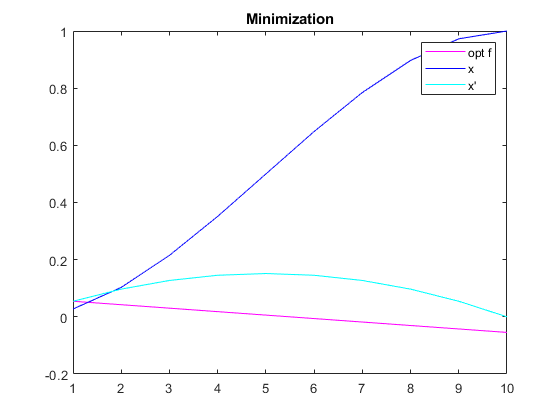

% from state space equations
A = [1, 1; 0, 1];
b = [0.5; 1];
y=[1;0];

% polynomial fun
A_poly = [A^9*b, A^8*b, A^7*b, A^6*b, A^5*b, A^4*b, A^3*b, A^2*b, A^1*b, A^0*b];

% underdetermined case x*
p_n = A_poly'*inv(A_poly*A_poly')*y; % x* is the force

% for each n=1 to 10
x = zeros(2,10);
for n = 1:10
    if n == 1
        x(:,1) = A*[0 0]' + b*p_n(1); % initial rest condition x(0)=x'(0)=0
    else
        x(:,n) = A*x(:,n-1) + b*p_n(n); % x = Ax+b (see state-space equations)
    end
end

h(1) = plot(p_n, 'm');
hold on 
h(2) = plot(x(1, :), 'b');
hold on
h(3) = plot(x(2, :), 'c');
title('Minimization');
legend(h, 'opt f','x', "x'");
hold off

This result makes sense since force is a decreasing linear line such that the distance of the mass continuously increases more at time 0 and less at time 10.

## Additional specification

Adding $x\left(5\right)=0$ requiring mass to be at position 0 at time 5.

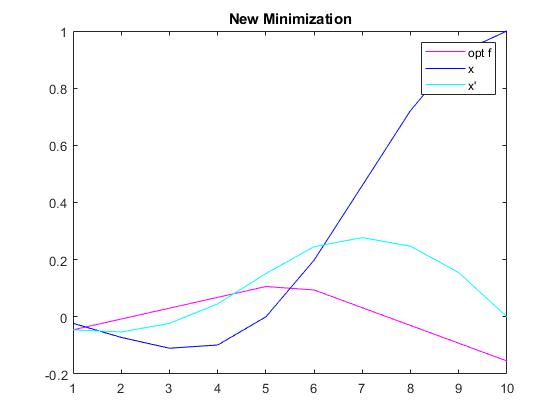

y = [1;0;0]; % update y

% only the last 4 
A_additional = [A_poly(1, 6:10), 0, 0, 0, 0, 0];
A_new = [A_poly;A_additional];

% using new A, still underdetermined case
p_n = A_new'*inv(A_new*A_new')*y;

% for each n=1 to 10
X = zeros(2,10);
for i = 1:10
    if i == 1
        X(:,1) = A*[0 0]' + b*p_n(1); 
    else
        X(:,i) = A*X(:,i-1) + b*p_n(i); 
    end
end

% plotting
g(1) = plot(p_n, 'm');
hold on 
g(2) = plot(X(1, :), 'b');
hold on
g(3) = plot(X(2, :), 'c');
title('New Minimization')
legend(g, 'opt f','x', "x'")